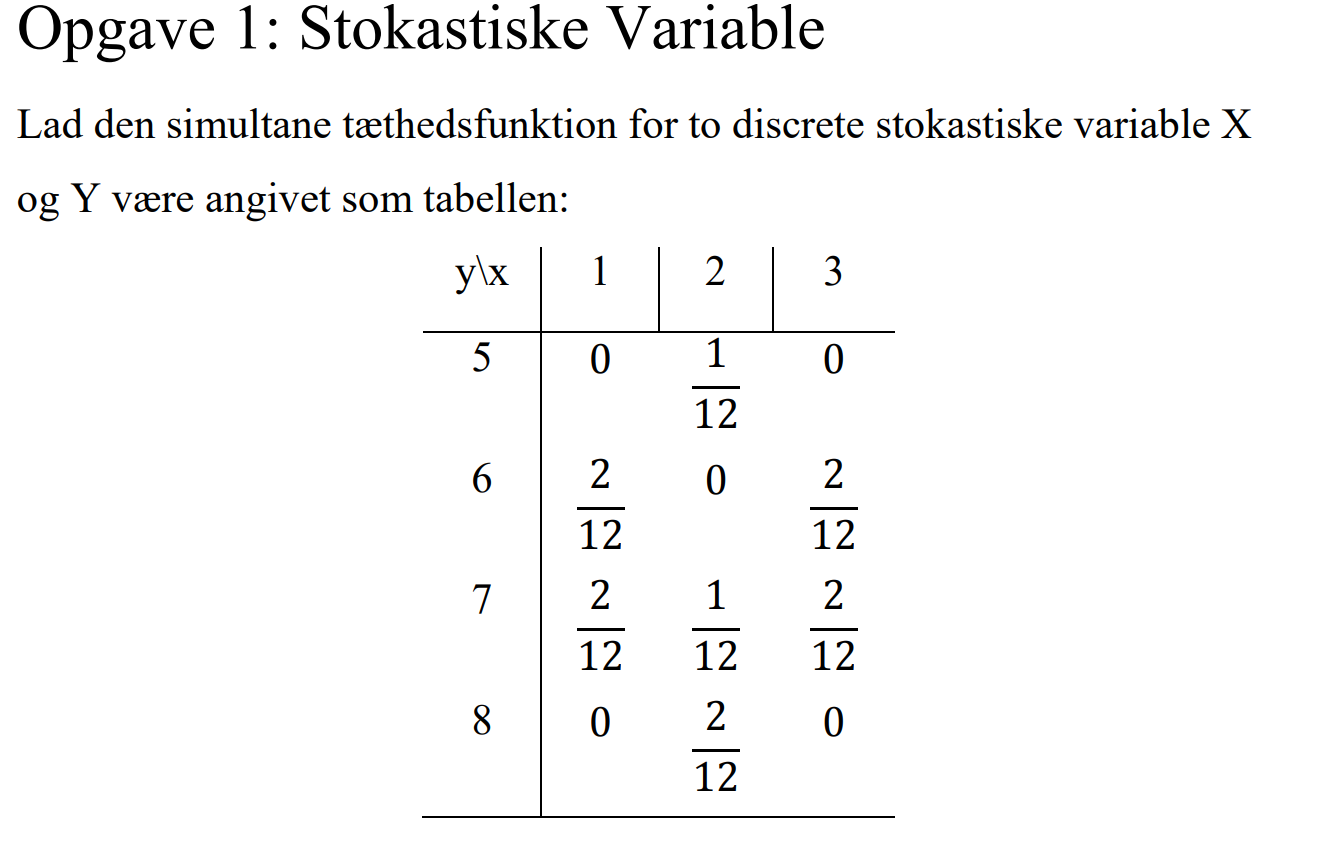

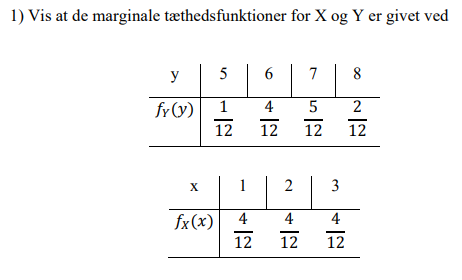

Matlab code)

XMatrix =[ 1 2 3];
YMatrix = [5;6;7;8];
Matrix = [0 1/12 0; 2/12 0 2/12; 2/12 1/12 2/12; 0 2/12 0];

X = sum(Matrix);
Y = sum(Matrix,2);
format rat
X %Svar

X =        1/3            1/3            1/3     


Y % Svar

Y =        1/12    
       1/3     
       5/12    
       1/6     


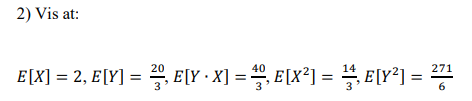

E_x = sum(XMatrix.*X)

E_x =        2       


E_Y = sum(YMatrix .* Y)

E_Y =       20/3     


EYX=E_x * E_Y

EYX =       40/3     


EX2 = sum(XMatrix.^2 .* X)

EX2 =       14/3     


EY2 = sum(YMatrix.^2 .* Y)

EY2 =      271/6     


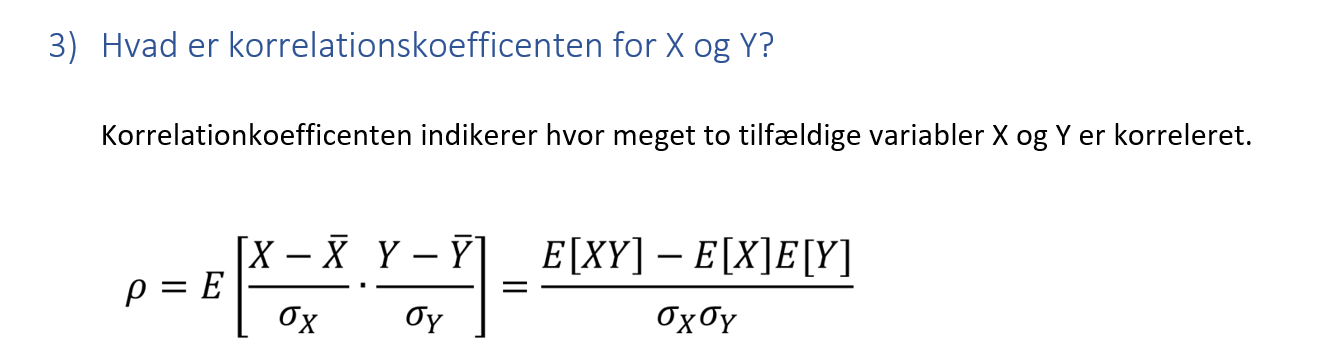

VarX = EX2-(E_x.^2);
VarY = EY2 - (E_Y.^2);

p =(EYX - E_x .* E_Y)/(sqrt(VarX)*sqrt(VarY))

p =        0       


- Da korrelationkoefficienten er 0, er X og Y ukorrelerede. 

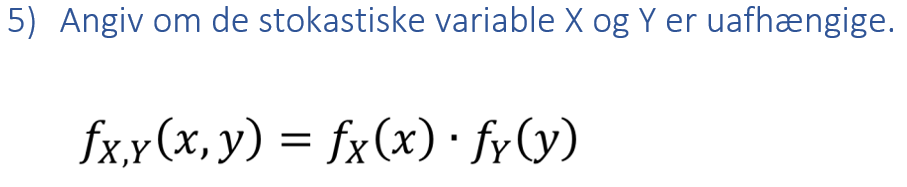

inde = kron(Y,X)

inde =        1/36           1/36           1/36    
       1/9            1/9            1/9     
       5/36           5/36           5/36    
       1/18           1/18           1/18    


- Da fx(x)*fy(y) ikke er identisk med fxy(x,y) er X og Y ikke uafhængige. 

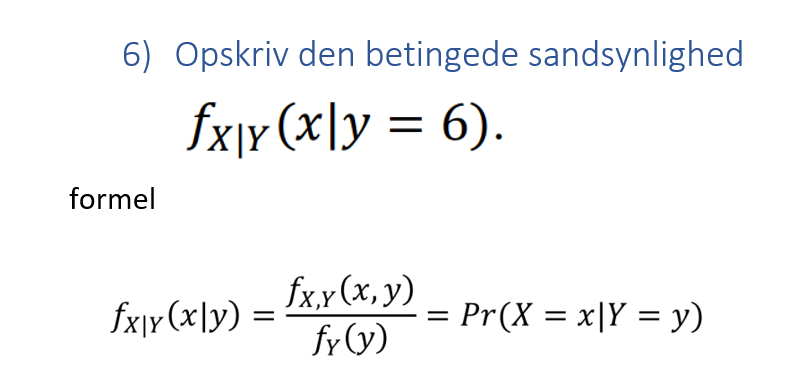

fxy= Matrix(2,:)./Y(2)

fxy =        1/2            0              1/2     


Opgave 2 

clear
clc
format


Matlab code for opgave 1

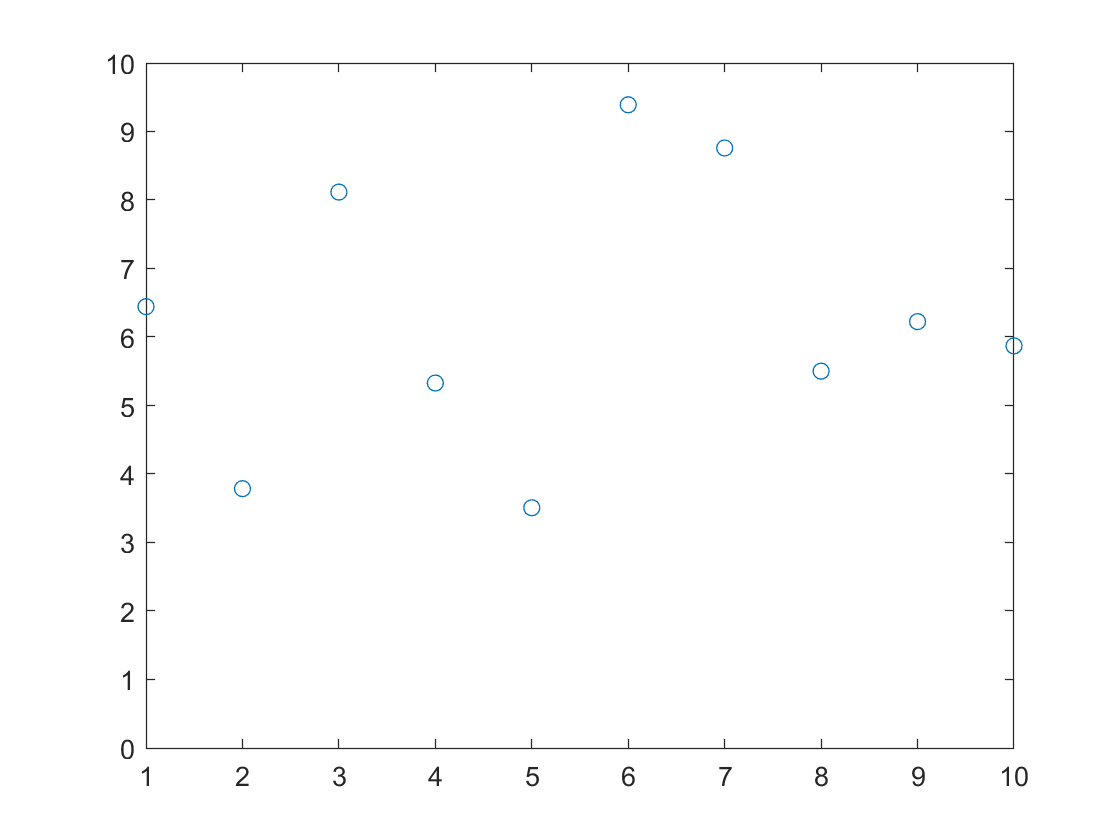

for(n = 1:10)
    X(n) = rand * 10;
end
figure(1)
plot(X,'o')
ylim([0 10])

Opgave 2 

mean = (10+0)/2

mean = 5

variance = 1/12*(10-0).^2

variance = 8.3333

Opgave 4 ----

Opgave 1

clear
clc

antal = [5562 4357 3471 3078 2309 1285 969 602 238 268];
years = [1901:10:1991];

antalMean = mean(antal)

antalMean = 2.2139e+03

yearsMean = mean(years)

yearsMean = 1946

Benytter følgende formel for at finde skæringen og hældningen

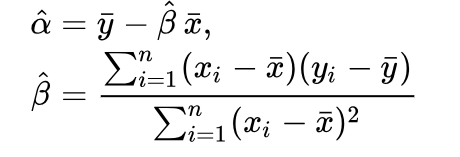

%Parameter estimat hældning
Beta = sum((antal - antalMean) .* (years - yearsMean)) / sum((years - yearsMean).^2)

Beta = -59.5000


% Parameter estimat skæring
Alpha = antalMean - Beta * yearsMean

Alpha = 1.1800e+05

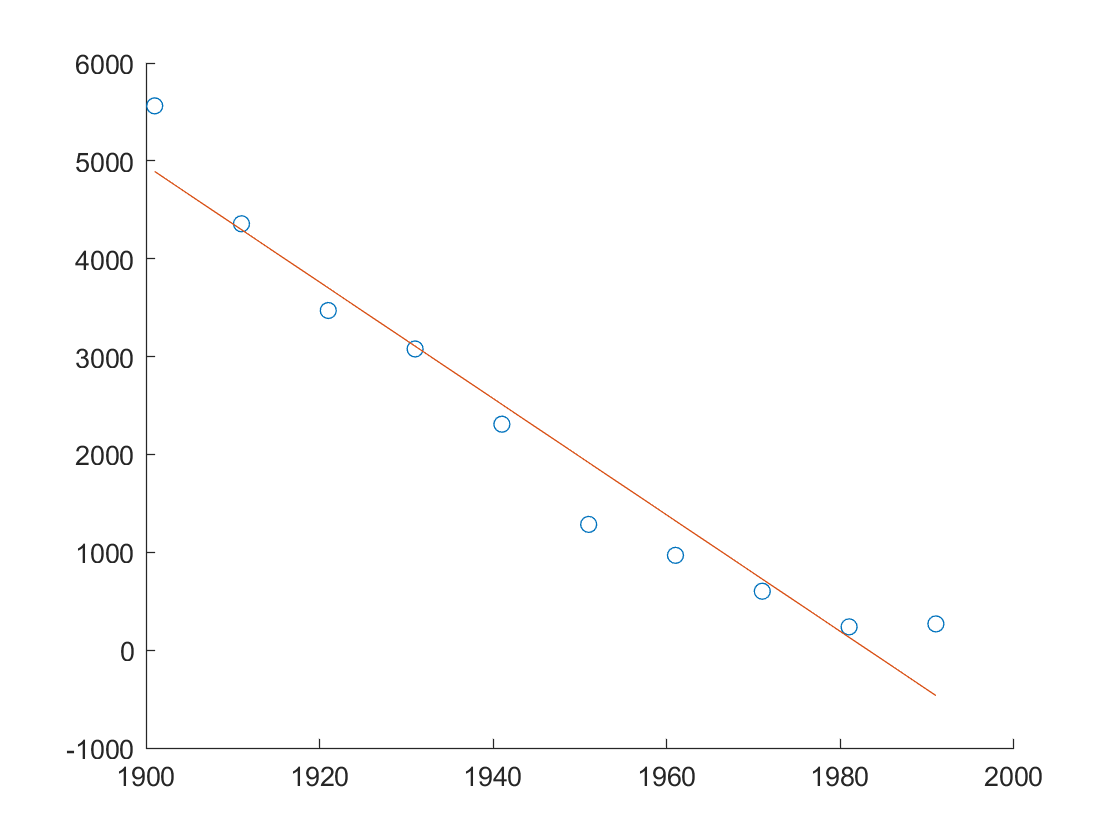

linearModel = Alpha + years * Beta;
figure(2)
hold on
scatter(years, antal)
plot(years,linearModel)

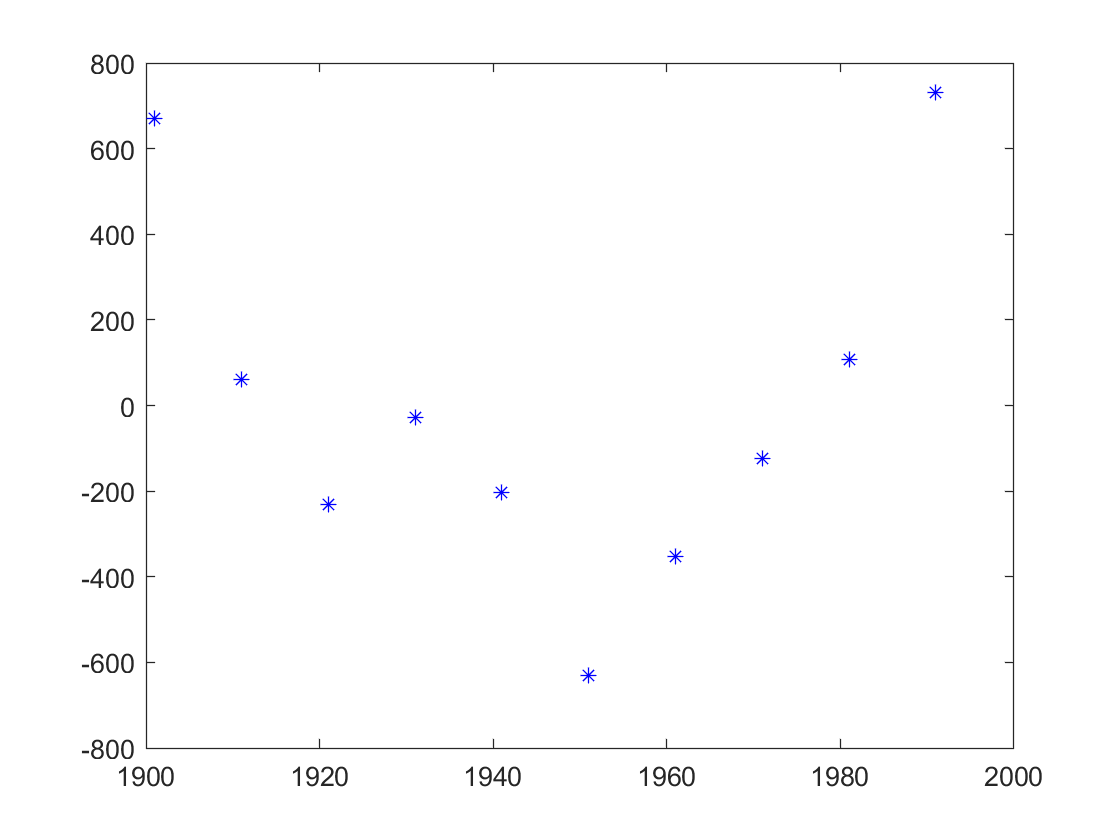

Residualtegning = antal - linearModel;
figure(3)
plot(years,Residualtegning,'b*')

Først findes standard deviationen 

n = length(antal)

n = 10

sr2 = 1/(n-2)*sum((Residualtegning).^2)

sr2 = 2.0415e+05

t0 = tinv(0.975,(n-2))

t0 = 2.2809

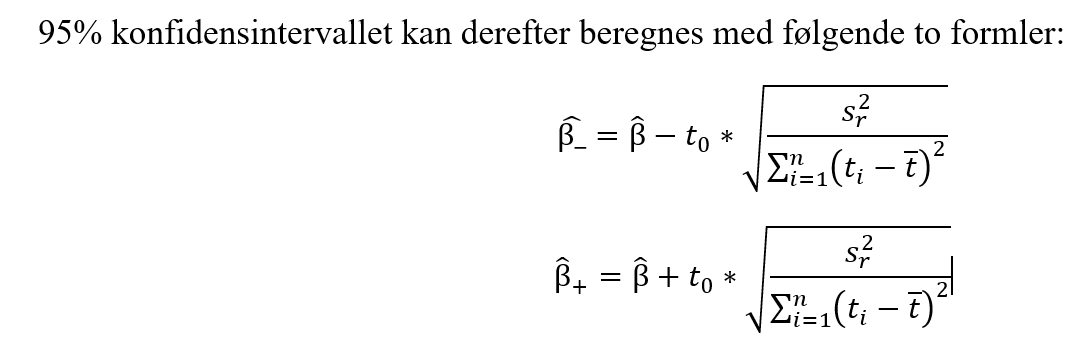

ConfMinus = Beta - t0 *sqrt(sr2/sum((years - yearsMean).^2))

ConfMinus = -70.8461

ConfPositiv = Beta + t0 *sqrt(sr2/sum((years - yearsMean).^2))

ConfPositiv = -48.1539

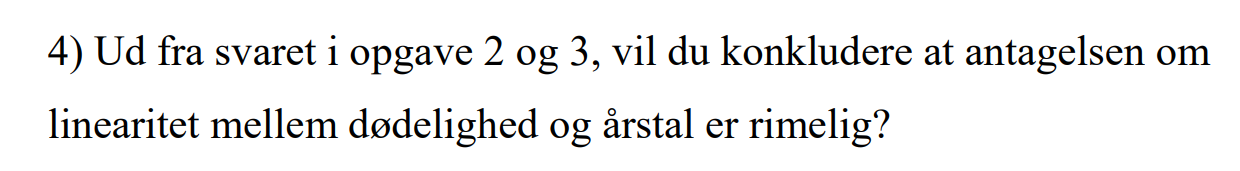

Der er umiddelbart for få målepunkter, dog kunne det indiker at der er en lineær tedens, men residual plottet viser at residulaerne systemadisk ligger under 0 mellem årerne 1920-1970, og derudover vil data afvige mere efter 1991, da dødeligeheden ikke kan være negativ.

Linearitet er ikke en god antagelse.